%path = "C:\Users\miech\OneDrive - Politechnika Warszawska\PMT-badanie\C1--hv--final00--00000samples.csv";
path = "C:\Users\miech\Documents\HyperK\Dane\JMarzec\CFD\C1--hv--10700---00000samples.csv";
% path = "C:\Users\mnurek\Documents\HK\Dane\JMarzec\CFD\C1--hv--10700---00000samples.csv";
pmt_data = csvread(path);
pmt_data = pmt_data';

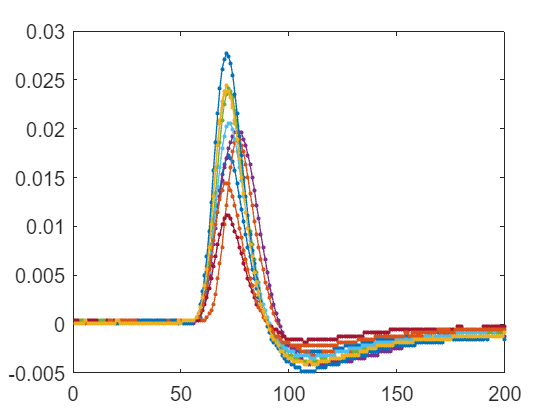

waveforms = pmt_data(:,1:10);
waveform_len = length(waveforms);

% Filter <0.3PE pulses
waveforms = waveforms(:,max(waveforms) > 0.01);
[amplitudes, max_indexes] = get_amplitudes(waveforms);

plot(1:waveform_len, waveforms, ".-")

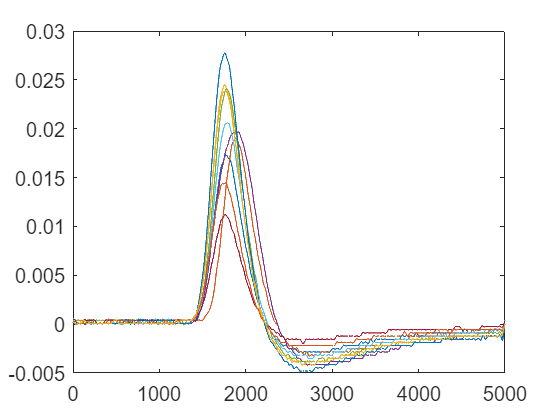

% FFT interpolation of original waveform
brb_interpolation_factor = 4; %Ts 8ns -> 2ns

interpolation_factor = 25; %Ts 2ns -> 80ps
interpolated_waveform = interpft(waveforms,waveform_len * interpolation_factor);
interpolated_waveform_len = length(interpolated_waveform);

final_interpolation_factor = brb_interpolation_factor*interpolation_factor;
plot(0:interpolated_waveform_len - 1, interpolated_waveform)

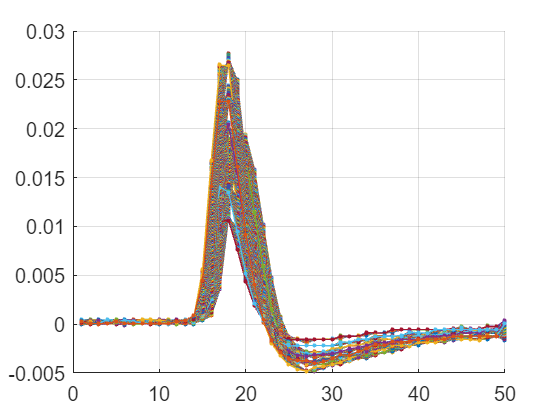

% Get amplitude paramater for different Ts 8ns waveforms
interpolated_waveform_shift = [-40:39]';
amplitude_parameters = zeros(length(interpolated_waveform_shift), size(interpolated_waveform, 2));

figure; hold on; grid on;
for k = 1 : size(interpolated_waveform, 2)
    interpolated_waveform_max_index = max_indexes(k);
    for n = 1 : 80
        current_interpolated_waveform_shift = interpolated_waveform_shift(n);
        current_waveform = interpolated_waveform(interpolated_waveform_max_index + current_interpolated_waveform_shift:final_interpolation_factor:interpolated_waveform_len, k);
        amplitude_parameters(n,k) = get_amplitude_parameter(current_waveform);
        plot(1:length(current_waveform), current_waveform, ".-")
    end
end

hold off;

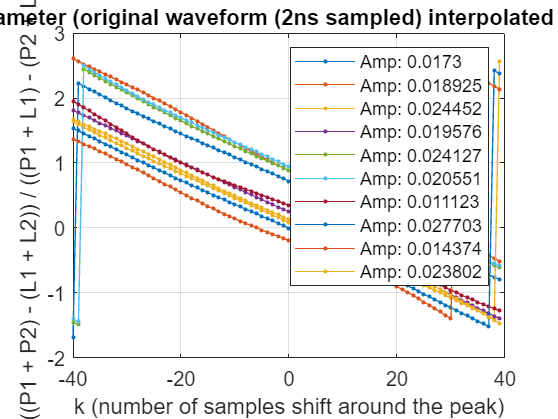

plot(interpolated_waveform_shift, amplitude_parameters * 2, ".-"); grid on;
title("peak amplitude parameter (original waveform (2ns sampled) interpolated x25 -> 25 data points)")
ylabel("((P1 + P2) - (L1 + L2)) / ((P1 + L1) - (P2 + L2))")
xlabel("k (number of samples shift around the peak)")
legendLabels = "Amp: " + string(amplitudes);
legend(legendLabels)

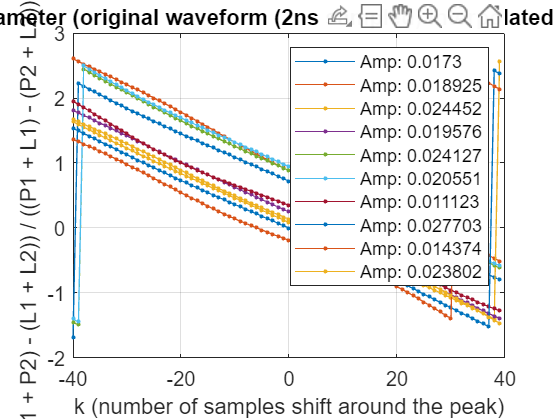

time_shift = amplitude_parameters * 2;
plot(interpolated_waveform_shift, time_shift, ".-"); grid on;
title("peak amplitude parameter (original waveform (2ns sampled) interpolated x25 -> 25 data points)")
ylabel("((P1 + P2) - (L1 + L2)) / ((P1 + L1) - (P2 + L2)) * 2 ns")
xlabel("k (number of samples shift around the peak)")
legendLabels = "Amp: " + string(amplitudes);
legend(legendLabels)

% Chec the results
[~, interpolated_waveform_max_indexes] = max(interpolated_waveform);
interpolated_waveform_max_indexes = interpolated_waveform_max_indexes - 1;

waveform_max_indexes = (max_indexes-1) * interpolation_factor;
difference = abs(interpolated_waveform_max_indexes - waveform_max_indexes);
difference_time = difference / final_interpolation_factor * 8;
result = time_shift(40,:) - difference_time;

function [amplitudes, max_indexes] = get_amplitudes(waveforms)
    [amplitudes, max_indexes] = max(waveforms);
end
function [amplitude_parameter] = get_amplitude_parameter(waveform)
    % Find maximum index for waveform
    [~, max_index] = max(waveform);
    
    L1_index = max_index - 1; L1 = waveform(L1_index);
    L2_index = max_index - 2; L2 = waveform(L2_index);
    P1_index = max_index + 1; P1 = waveform(P1_index);
    P2_index = max_index + 2; P2 = waveform(P2_index);

    amplitude_parameter = ((P1 + P2) - (L1 + L2)) / ((P1 + L1) - (P2 + L2));
end

